# **OpenTSEA - Tsunami VDPO Analysis Toolkit**

### © Jonas Cels, 2025

Version 1.0

Units: m, kN

% home directory
homedir = [pwd '/'];
projectFolder = 'EXAMPLE_PROJECT';
LIST_FEMscenarios = 'LIST_FEM_scenarios';

aggregateColumnShearSprings = 1; % aggregate shear springs to fibre sections
beam_recorders = 0; % record beam outputs
FEM_scenarios = readtable([projectFolder '/' LIST_FEMscenarios '.xlsx'], ...
    'VariableNamingRule','preserve');

structuralModels = FEM_scenarios.structureFEM;

for SM = 1:numel(structuralModels)
    scenario = FEM_scenarios.TsunamiScenarios{SM};
    tsunamiScenarios_xlsx = [homedir projectFolder '/' scenario '.xlsx'];
    if exist(tsunamiScenarios_xlsx,"file")
        opts_TsunamiScenarios = detectImportOptions(tsunamiScenarios_xlsx, ...
            "Range", "B12:B112", 'VariableNamingRule','preserve');
        Tbl_TsunamiScenarios = readtable(tsunamiScenarios_xlsx, opts_TsunamiScenarios);
        Tbl_TsunamiScenarios = rmmissing(Tbl_TsunamiScenarios, "DataVariables", 1);
        FEM_scenarios.AnalysisScenarios(SM) = {Tbl_TsunamiScenarios};
    else
        error('Scenario model does not exist in directory.');
    end
end

### File directories for each structural model

buildDirectories = 1; % build the directories prior to analysis
DIRECTORIES = cell(height(structuralModels),1);
[DIRECTORIES] = directoriesStructure(DIRECTORIES, homedir, ...
    projectFolder, FEM_scenarios, buildDirectories);

### Construct the structural models in opensees

for SM = 1:height(structuralModels)
    directories = DIRECTORIES{SM};
    inputModel = directories.structuralModel;
    disp(['Building the ' inputModel ' OpenSees model.']);

    % Options
    runGravityAnalysis = 1;
    plot_gravityForces = 1;
    plot3Dstruct = 1;
    plotInfillCapacities = 0;

    % Build the OpenSees structural model
    [~] = StructuralModelBuilder(directories, ...
        aggregateColumnShearSprings, runGravityAnalysis, ...
        plot_gravityForces, plot3Dstruct, plotInfillCapacities);
end

Building the Y_3z_9x_2y_GF0Q_F1Q_I2Q_B2Q OpenSees model.




         OpenSees -- Open System For Earthquake Engineering Simulation
                 Pacific Earthquake Engineering Research Center
                        Version 3.5.1 64-Bit

      (c) Copyright 1999-2016 The Regents of the University of California
                              All Rights Reserved
  (Copyright and Disclaimer @ http://www.berkeley.edu/OpenSees/copyright.html)


Building model applying vertical loads ...
Structural model built and gravity analysis complete - gravity loads held constant



### File directories for each tsunami analysis model

buildDirectories = 1; % used to build the directories prior to analysis
[DIRECTORIES] = directoriesAnalyses(DIRECTORIES, FEM_scenarios, buildDirectories);

### Construct the tsunami analysis inputs for opensees for each structure

for SM = 1:height(structuralModels)
    directories = DIRECTORIES{SM};
    inputModel = directories.structuralModel;
    disp(['Building:' inputModel ' tsunami analysis models']);

    plot_lateral_forces = "on";
    plot_vertical_forces = "on";

    plot_3D_forces = "on";
    plot_3D_animation = "off";

    [tm] = TsunamiModelBuilder(directories, [], aggregateColumnShearSprings, beam_recorders, ...
        plot_lateral_forces, plot_vertical_forces, ...
        plot_3D_forces,plot_3D_animation,true);
    disp(['The ' inputModel ' tsunami analysis models are built.']);
    close all;
end

Building:Y_3z_9x_2y_GF0Q_F1Q_I2Q_B2Q tsunami analysis models


VDPO_y_F100_bw010: Fr = 1; Frc = 0.68283; bw = 0.1
Elapsed time is 207.133988 seconds.


The Y_3z_9x_2y_GF0Q_F1Q_I2Q_B2Q tsunami analysis models are built.


## Run tsunami analyses

for SM = 1:height(structuralModels)
    directories = DIRECTORIES{SM};

    run_VDPO = 1;
    run_VDPO2 = 0;
    plot_pushovercurve = 1;
    plot_baseReactions = 0;
    plot_3D_response = 1;
    plot_3D_animation = 0;

    RunTsunamiAnalysis(directories, [], [], ...
        aggregateColumnShearSprings, ...
        run_VDPO, ...
        run_VDPO2, ...
        plot_pushovercurve);
end

Running analysies for: Y_3z_9x_2y_GF0Q_F1Q_I2Q_B2Q


## Post Processing: clean numerical anomalies

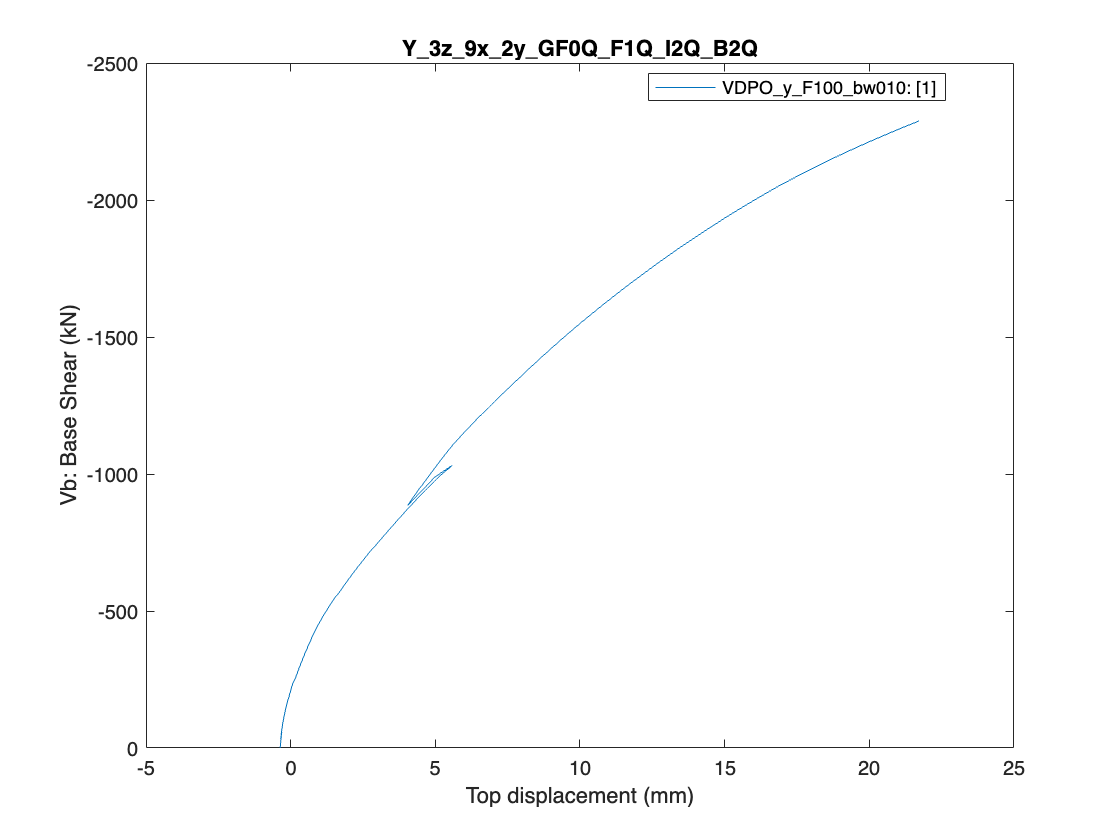

% print the timestep of each EDP for each structural element
for SM = 1:height(structuralModels)
    directories = DIRECTORIES{SM};
    % Assess the Engineering Demand Parameters
    postProcess_trimSpikes(directories,5);
end

## Post Processing: Engineering Demand Parameters

% print the timestep of each EDP for each structural element
for SM = 1:height(structuralModels)
    directories = DIRECTORIES{SM};
    % Assess the Engineering Demand Parameters
    EDP_postProcessor(directories,0,1,1,1,0,0,0,1,1,1,1);
end

## Post Processing: Figures

maxColumnlvlPlot = 1; % maximum level for column level plots
for SM = 1:height(structuralModels)
    directories = DIRECTORIES{SM};

    PostProcessorFigures(directories,maxColumnlvlPlot,0,0,1,1,1,1,1);
    %%% PostProcessorFigures
    % directories
    % columnlvlPlot
    % plot_pushoverScenarios
    % plot_3D_forces
    % plot_3Danimation_forces
    % plot_pushoverCurve
    % plot_baseReactions
    % plot_3Dresponse
    % plot_columnForceDisplacements
    % plot_MNinteraction
    % plot_MaterialStrains
    % plot_maxShearDeformation
    % plot_pushoverCurvesEDPs
    % plot_3Danimation_response
    % plot_3DresponseEDPs
end

#### Clean up redundant data after post-processing

 % clear the redundant OpenSees .txt processing data.
 % (all input and output data remains accessible within
 % the input and output data objects)
 removeProcessingData = 1;
 if removeProcessingData == 1
     for SM = 1:height(structuralModels)
         directories = DIRECTORIES{SM};
         targetDir = directories.dirOpenSeesModel;
         % Exclude the special folders and other non-target files
         tsunamiModelsobj = [directories.structuralModel '_' directories.tsunamiScenariosList];
         filesToKeep = {directories.structuralModel, tsunamiModelsobj};
         foldersToKeep = {'Analysis Results', 'Figures'};

         delete_except(filesToKeep, foldersToKeep, targetDir);
     end
 end

function delete_except(selectedFiles, selectedFolders, targetDirectory)
    % Deletes all files and folders in the target directory except those specified

    % selectedFiles: cell array of filenames to be kept
    % selectedFolders: cell array of folder names to be kept
    % targetDirectory: directory where files and folders will be deleted

    % Check if the target directory exists
    if ~isfolder(targetDirectory)
        error('Target directory does not exist.');
    end

    % Change to target directory
    oldFolder = cd(targetDirectory);
    allFilesFolders = dir;

    % Check the selected files exist
    if ~any(isfile(selectedFiles))
        error('Selected files do not exist.')
    end
    % Check the selected folders exist
    if ~any(isfolder(selectedFolders))
        error('Selected folders do not exist.')
    end

    for k = 1:length(allFilesFolders)
        itemName = allFilesFolders(k).name;

        % Skip the current and parent directory references
        if strcmp(itemName, '.') || strcmp(itemName, '..')
            continue;
        end
        
        if ~ismember(itemName, selectedFiles) && ~ismember(itemName, selectedFolders)
            if allFilesFolders(k).isdir
                rmdir(itemName, 's');
            else
                delete(itemName);
            end
        end
    end
    cd(oldFolder);
end